cd("G:\Other computers\My laptop\Workarea\Research\ThesisII\DATA")



%inst = readtable("realinstrument.csv")
%irate = readtable("irate.csv")
hicp = readtable("hicp.csv")

hicp = 328×5 table
       date       conf        status1          s1       comment  
    __________    ____    ________________    _____    __________

    1996-01-31    NaN     {'Normal value'}    70.97    {0×0 char}
    1996-02-29    NaN     {'Normal value'}    71.29    {0×0 char}
    1996-03-31    NaN     {'Normal value'}    71.54    {0×0 char}
    1996-04-30    NaN     {'Normal value'}    71.66    {0×0 char}
    1996-05-31    NaN     {'Normal value'}    71.83    {0×0 char}
    1996-06-30    NaN     {'Normal value'}    71.84    {0×0 char}
    1996-07-31    NaN     {'Normal value'}    71.84    {0×0 char}
    1996-08-31    NaN     {'Normal value'}     71.8    {0×0 char}
    1996-09-30    NaN     {'Normal value'}    71.93    {0×0 char}
    1996-10-31    NaN     {'Normal value'}       72    {0×0 char}
    1996-11-30    

indprod = readtable("ind prod adj.csv")

indprod = 387×2 table
       date        s1 
    __________    ____

    31/01/1991    82.5
    28/02/1991    81.5
    31/03/1991    80.7
    30/04/1991    80.2
    31/05/1991    80.2
    30/06/1991    81.7
    31/07/1991    80.2
    31/08/1991    80.1
    30/09/1991    80.3
    31/10/1991    80.6
    30/11/1991    81.5
    31/12/1991    80.9
    31/01/1992    81.9
    29/02/1992    82.2
    31/03/1992    81.4
    30/04/1992    81.3


unemp = readtable("unemp adj.csv")

unemp = 339×2 table
       date         s1  
    __________    ______

    31/01/1995    10.885
    28/02/1995    10.843
    31/03/1995    10.791
    30/04/1995    10.734
    31/05/1995    10.742
    30/06/1995    10.784
    31/07/1995    10.847
    31/08/1995     10.89
    30/09/1995    10.934
    31/10/1995    10.958
    30/11/1995    10.976
    31/12/1995    10.959
    31/01/1996    10.935
    29/02/1996    10.928
    31/03/1996    10.925
    30/04/1996    11.007




ebpre = readtable("ebp.csv")

ebpre = 285×5 table
       date        rate_nfc_ea    spr_nfc_bund_ea    spr_nfc_dom_ea    spr_bk_dom_ea
    ___________    ___________    _______________    ______________    _____________

    {'1999m1' }       4.47             1.15               1.16             0.66     
    {'1999m2' }       4.55             0.92               0.94             0.63     
    {'1999m3' }       4.51             0.97               0.98              0.7     
    {'1999m4' }       4.33             1.01               0.98             0.74     
    {'1999m5' }        4.5             0.94               0.93              0.7     
    {'1999m6' }       4.95             0.87               0.89             0.59     
    {'1999m7' }        5.2             0.89                0.9             0.71     
    {'1999m8' }       5.37              0.9 

ebp = ebpre{53:251,"spr_bk_dom_ea"}

ebp =     0.7800
    0.7300
    0.6600
    0.6300
    0.6900
    0.6200
    0.6000
    0.6000
    0.6200
    0.6300


%Loading instruments
inst1 = readtable("realinstrumentSW.csv")

Error using readtable
Unable to find or open 'realinstrumentSW.csv'. Check the path and filename or file permissions.

inst2 = readtable("realinstrument1M.csv")
inst3 = readtable("realinstrument3M.csv")
inst4 = readtable("realinstrument6M.csv")
inst5 = readtable("realinstrument1Y.csv")
inst6 = readtable("realinstrument2Y.csv")


%Loading interest rates
%irate1 = readtable("ois sw hist.csv", range = "A18:E258")
%irate2 = readtable("ois 3m hist.csv", range = "A18:E258")
irate3 = readtable("ois 1y.csv", range = "A18:E258")
irate4 = readtable("ois 2y.csv", range="A18:E258")

%irate3 = readtable("euribor 3m.csv")
%irate4 = readtable("euribor 6m.csv")

irate5 = readtable("euribor 1y.csv")
%irate6 = readtable("eonia.csv")

%Separating data

% instru1 = flipud(inst1{:, "Values"}); %inst{2:261,"Var2"}
% instru2 = flipud(inst2{:, "Values"});
% instru3 = flipud(inst3{:, "Values"});
% instru4 = flipud(inst4{:, "Values"});
% instru5 = flipud(inst5{:, "Values"});
% instru6 = flipud(inst6{:, "Values"});


instru1 = inst1{:, "Values"}; %inst{2:261,"Var2"}
instru2 = inst2{:, "Values"};
instru3 = inst3{:, "Values"};
instru4 = inst4{:, "Values"};
instru5 = inst5{:, "Values"};
instru6 = inst6{:, "Values"};

instru = [instru1 instru2 instru3 instru4 instru5 instru6]

%inrate = irate{109+4:end-25, "s1"};
inf = hicp{85+4:312-25, "s1"};
indp = indprod{145+4:372-25, "s1"};
une = unemp{101:299, "s1"};

%inrate1 = flipud(irate1{43:end, "Var5"});
%inrate2 = flipud(irate2{43:end, "Var5"});
inrate3 = flipud(irate3{43:end, "Var5"});
inrate4 = flipud(irate4{43:end, "Var5"})
%inrate5 = flipud(irate5{43:end, "Var5"});

 
% inrate3 = irate3{113:311, "s1"};
% inrate4 = irate4{113:311, "s1"};
%inrate5 = irate5{113:311, "s1"};
% inrate6 = irate6{113:311, "s1"};

%inrate = [inrate1 inrate2 inrate3 inrate4 inrate5]
alinf = hicp{37:312-25, "s1"};
alun = unemp{49:299, "s1"}; 
alebp = ebpre{1:251,"spr_bk_dom_ea"}
alirate = irate5{61:311, "s1"}
alindp = indprod{97:372-25, "s1"};

datal = [alirate log(alinf) alun log(alindp) alebp]

%Loading pure instruments

pinst1 = readtable("Pure Instruments\\realinstrumentSW.csv")

pinst1 = 216×3 table
    Var1       Month       Values
    ____    ___________    ______

      0     {'2002-01'}        0 
      1     {'2002-02'}     2.75 
      2     {'2002-03'}        0 
      3     {'2002-04'}        0 
      4     {'2002-05'}        0 
      5     {'2002-06'}       -1 
      6     {'2002-07'}        0 
      7     {'2002-08'}        0 
      8     {'2002-09'}      0.5 
      9     {'2002-10'}      2.5 
     10     {'2002-11'}      8.8 
     11     {'2002-12'}     -7.8 
     12     {'2003-01'}     -0.5 
     13     {'2003-02'}        2 
     14     {'2003-03'}      5.2 
     15     {'2003-04'}        2 


% inst2 = readtable("realinstrument1M.csv")
% inst3 = readtable("realinstrument3M.csv")
% inst4 = readtable("realinstrument6M.csv")
pinst5 = readtable("Pure Instruments\\realinstrument1Y.csv")

pinst5 = 216×3 table
    Var1       Month       Values
    ____    ___________    ______

      0     {'2002-01'}       -1 
      1     {'2002-02'}     2.75 
      2     {'2002-03'}        1 
      3     {'2002-04'}        0 
      4     {'2002-05'}     0.45 
      5     {'2002-06'}     -1.5 
      6     {'2002-07'}      0.2 
      7     {'2002-08'}     -0.2 
      8     {'2002-09'}        1 
      9     {'2002-10'}        0 
     10     {'2002-11'}     2.35 
     11     {'2002-12'}     -0.3 
     12     {'2003-01'}      1.1 
     13     {'2003-02'}      0.5 
     14     {'2003-03'}        1 
     15     {'2003-04'}      0.7 


pinst6 = readtable("Pure Instruments\\realinstrument2Y.csv")

pinst6 = 216×3 table
    Var1       Month       Values
    ____    ___________    ______

      0     {'2002-01'}       -1 
      1     {'2002-02'}      2.5 
      2     {'2002-03'}     1.25 
      3     {'2002-04'}      0.5 
      4     {'2002-05'}        0 
      5     {'2002-06'}       -1 
      6     {'2002-07'}      0.5 
      7     {'2002-08'}       -1 
      8     {'2002-09'}      0.5 
      9     {'2002-10'}    -1.25 
     10     {'2002-11'}     1.05 
     11     {'2002-12'}      1.2 
     12     {'2003-01'}      1.2 
     13     {'2003-02'}      0.5 
     14     {'2003-03'}     -1.5 
     15     {'2003-04'}     0.05 



pinstru1 = pinst1{13:end, "Values"}; 
%pinstru2 = pinst2{:, "Values"};
%pinstru3 = pinst3{:, "Values"};
%pinstru4 = pinst4{:, "Values"};
pinstru5 = pinst5{13:end, "Values"};
pinstru6 = pinst6{13:end, "Values"};

pinstru = [pinstru1 pinstru5 pinstru6]

pinstru =    -0.5000    1.1000    1.2000
    2.0000    0.5000    0.5000
    5.2000    1.0000   -1.5000
    2.0000    0.7000    0.0500
    0.9500   -1.0000   -2.0000
   -8.7500   -2.5000   -1.9500
   -0.5000    0.2500   -0.2500
         0         0         0
         0    0.3000    0.0500
    1.0000   -0.7500   -0.7000


varnames = {'Instrument', 'Interest rate', 'HICP', 'Unemp', 'Ind Prod', 'EBP'};
shocknames = {'Instrument', 'Interest rate', 'HICP', 'Unemp', 'Ind Prod', 'EBP'};

lags = 4

lags = 4

figure
for k = 1:3

    data = [pinstru(:,k) inrate5 log(inf) une log(indp) ebp];
    
    data = flipud(data);
    
    [betas, resids] = VAR(data,lags,1);
    
    irfs = woldirf(betas,1,lags,47);
    
    sig1 = cov(resids);
    
    S = chol(sig1)';
    
    [bootiv, upper, lower, boot_beta] = bootstrapIV(data, lags, 1, betas, resids, 1000, 48, 68, false);
    
    aux = repmat(inv(S), [1 1 48]);
    
    firfs = pagemtimes(irfs, aux);

    plotboot(6,48,firfs, upper, lower, varnames, shocknames,1)

end

Unrecognized function or variable 'inrate5'.

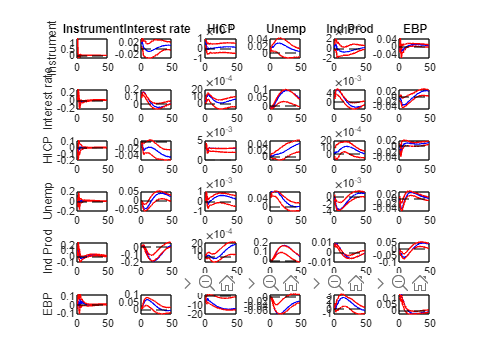

%Without loops
varnames = {'Instrument', 'Interest rate', 'HICP', 'Unemp', 'Ind Prod', 'EBP'};
shocknames = {'Instrument', 'Interest rate', 'HICP', 'Unemp', 'Ind Prod', 'EBP'};

figure

data = [instru5 inrate5 log(inf) une log(indp) ebp];
    
data = flipud(data);

[betas, resids] = VAR(data,lags,1);

irfs = woldirf(betas,1,lags,47);

sig1 = cov(resids);

S = chol(sig1)';

[bootiv, upper, lower, boot_beta] = bootstrapIV(data, lags, 1, betas, resids, 1000, 48, 68, false);

aux = repmat(S, [1 1 48]);

firfs = pagemtimes(irfs, aux);

plotboot(6,48,firfs, upper, lower, varnames, shocknames,1)





data = [instru(:,3) inrate5 log(inf) une log(indp)];
res = zeros(12,3)

res =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


for i = 1:12
    model = varm(5,i);
    est = estimate(model, data);
    res(i,:) = [i summarize(est).BIC summarize(est).AIC]
end

res = 1.0e+03 *

    0.0010   -2.5801   -2.6787
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


res = 1.0e+03 *

    0.0010   -2.5801   -2.6787
    0.0020   -2.7280   -2.9086
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


res = 1.0e+03 *

    0.0010   -2.5801   -2.6787
    0.0020   -2.7280   -2.9086
    0.0030   -2.6349   -2.8971
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


res = 1.0e+03 *

    0.0010   -2.5801   -2.6787
    0.0020   -2.7280   -2.9086
    0.0030   -2.6349   -2.8971
    0.0040   -2.5109   -2.8545
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


res = 1.0e+03 *

    0.0010   -2.5801   -2.6787
    0.0020   -2.7280   -2.9086
    0.0030   -2.6349   -2.8971
    0.0040   -2.5109   -2.8545
    0.0050   -2.4314   -2.8562
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


res = 1.0e+03 *

    0.0010   -2.5801   -2.6787
    0.0020   -2.7280   -2.9086
    0.0030   -2.6349   -2.8971
    0.0040   -2.5109   -2.8545
    0.0050   -2.4314   -2.8562
    0.0060   -2.3148   -2.8205
         0         0         0
         0         0         0
         0         0         0
         0         0         0


res = 1.0e+03 *

    0.0010   -2.5801   -2.6787
    0.0020   -2.7280   -2.9086
    0.0030   -2.6349   -2.8971
    0.0040   -2.5109   -2.8545
    0.0050   -2.4314   -2.8562
    0.0060   -2.3148   -2.8205
    0.0070   -2.2510   -2.8373
         0         0         0
         0         0         0
         0         0         0


res = 1.0e+03 *

    0.0010   -2.5801   -2.6787
    0.0020   -2.7280   -2.9086
    0.0030   -2.6349   -2.8971
    0.0040   -2.5109   -2.8545
    0.0050   -2.4314   -2.8562
    0.0060   -2.3148   -2.8205
    0.0070   -2.2510   -2.8373
    0.0080   -2.1326   -2.7993
         0         0         0
         0         0         0


res = 1.0e+03 *

    0.0010   -2.5801   -2.6787
    0.0020   -2.7280   -2.9086
    0.0030   -2.6349   -2.8971
    0.0040   -2.5109   -2.8545
    0.0050   -2.4314   -2.8562
    0.0060   -2.3148   -2.8205
    0.0070   -2.2510   -2.8373
    0.0080   -2.1326   -2.7993
    0.0090   -2.0270   -2.7738
         0         0         0


res = 1.0e+03 *

    0.0010   -2.5801   -2.6787
    0.0020   -2.7280   -2.9086
    0.0030   -2.6349   -2.8971
    0.0040   -2.5109   -2.8545
    0.0050   -2.4314   -2.8562
    0.0060   -2.3148   -2.8205
    0.0070   -2.2510   -2.8373
    0.0080   -2.1326   -2.7993
    0.0090   -2.0270   -2.7738
    0.0100   -1.9114   -2.7380


res = 1.0e+03 *

    0.0010   -2.5801   -2.6787
    0.0020   -2.7280   -2.9086
    0.0030   -2.6349   -2.8971
    0.0040   -2.5109   -2.8545
    0.0050   -2.4314   -2.8562
    0.0060   -2.3148   -2.8205
    0.0070   -2.2510   -2.8373
    0.0080   -2.1326   -2.7993
    0.0090   -2.0270   -2.7738
    0.0100   -1.9114   -2.7380


res = 1.0e+03 *

    0.0010   -2.5801   -2.6787
    0.0020   -2.7280   -2.9086
    0.0030   -2.6349   -2.8971
    0.0040   -2.5109   -2.8545
    0.0050   -2.4314   -2.8562
    0.0060   -2.3148   -2.8205
    0.0070   -2.2510   -2.8373
    0.0080   -2.1326   -2.7993
    0.0090   -2.0270   -2.7738
    0.0100   -1.9114   -2.7380


i=5

i = 5

mdl = fitlm(instru5(1:end-i),inrate4(1+i:end))

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)       1.5227     0.11437      13.314    4.4564e-29
    x1             -0.022478    0.078732    -0.28549       0.77557


Number of observations: 194, Error degrees of freedom: 192
Root Mean Squared Error: 1.59
R-squared: 0.000424,  Adjusted R-Squared: -0.00478
F-statistic vs. constant model: 0.0815, p-value = 0.776


data1 = [inrate5 log(inf) une log(indp)];
lags = 2

lags = 2

[b, r] = VAR(data1,lags,1);

ff = woldirf(b,1,lags,48);

%plotboot(4, 40, ff)

varnames = {'Interest rate', 'HICP', 'Unemp', 'Ind Prod', 'EBP'};
shocknames = {'Interest rate', 'HICP', 'Unemp', 'Ind Prod', 'EBP'};

%Second Method

dataiv = datal;

Unrecognized function or variable 'datal'.


dataiv = flipud(dataiv);

[betivs, residivs] = VAR(dataiv,lags,1);

coef = zeros(1,5)

for i = 1:5
    model = fitlm(flipud(pinstru6),residivs((end-198):end,i));
    betiv = model.Coefficients{2,1};
    coef(i) = betiv;
end

coef = coef./coef(1)

eirfs = woldirf(betivs,1,lags,47);

auxiv = repmat(coef, [5 1 48]);

ivirfs = eirfs.*auxiv;


[bootiv, upperiv, loweriv, boot_betaiv] = bootstrapSVARIV(flipud(pinstru6), dataiv, lags, 1, betivs, residivs, 1000, 48, 68);


figure
plotboot(5,48,ivirfs, upperiv, loweriv, varnames, shocknames,1)
